# **Assignment 3 - Lidar Localization**

**Name**: Sugumar Prabhakaran (id#: 994126815)

**Course**: ROB521 - Mobile Robotics

**Instructor**: Dr. Steven Waslander

**Due Date**: 13 Apr 2022

## Results and Analysis

### Question 1 - Implement Occupancy Grid Map 

Figure 1 shows the results of my occupancy grid map generated from lidar data.  To generate this map, the main intricacy was creating a RayTrace function, which calculates all the pixels from the robot's current pose to the end of the laser beam given a particular laser beam angle.  All the points up to the second-last pixel along this ray are treated as unoccupied, while the last pixel is treated as occupied.  As a result, the log-odds are adjusted and as the robot moves and the laser array sweeps around, we update the probability through log-odds for each cell that is viewed. One point to note is that the optimal values of alpha and beta were found to be:  ALPHA = +2 (for occupied cells) and BETA = -0.55 (for unoccupied cells), from experimenting.  For example, the four table legs, represented as dots in the bottom left were not always visible with lower beta values. Higher beta values would result in more light gray patches where it should be white.

**Note: **all helper functions and source code are in the Appendix.

**Figure 1 - Occupancy Grid Map**

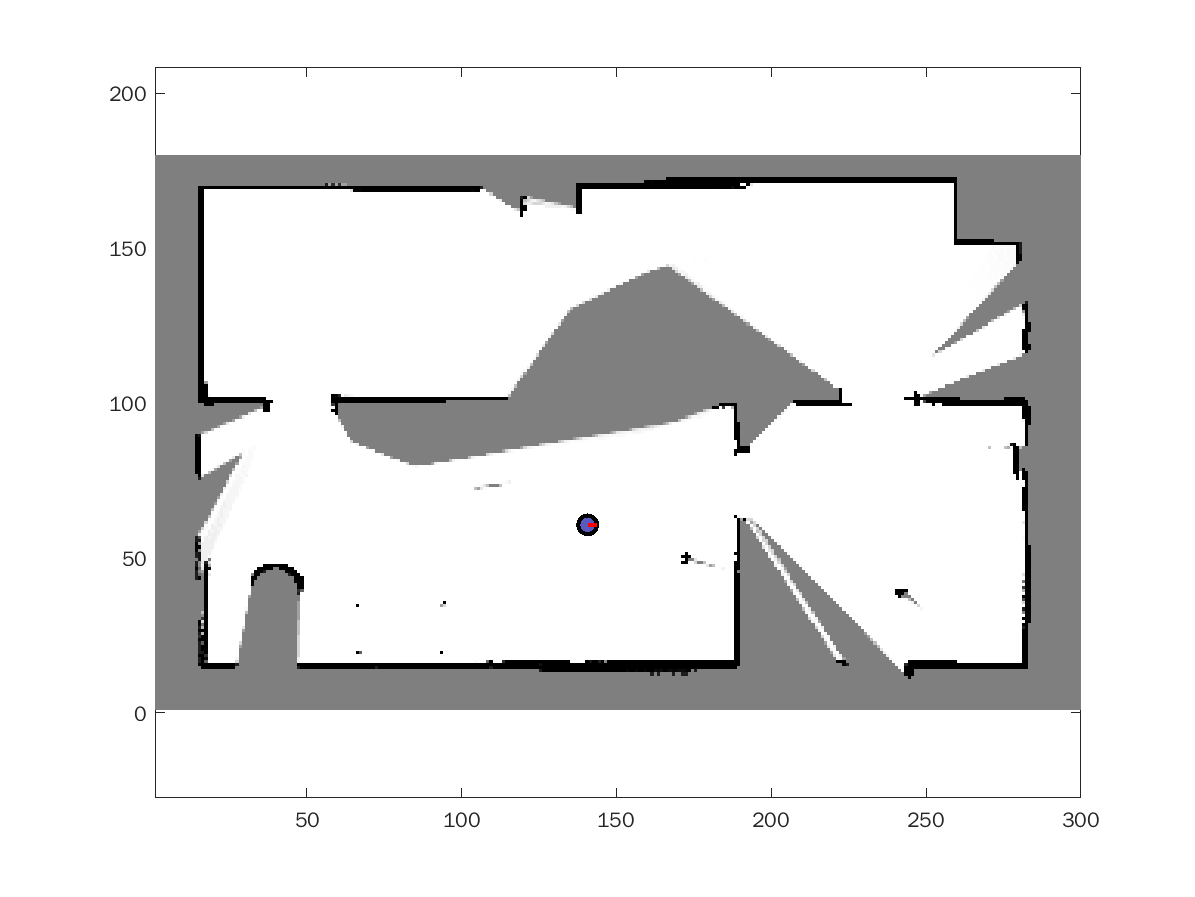

## Question 2 - Implement Particle Filter Localization

In part 2, we implemented a particle filter using 200 particles to localize the robot and the results are displayed in Figure 2. As we can see from the plot, the particle filter is consistently better than the odometry method of localization and it maintains its level of error over time, while the odometry tends to accumulate over time as it gets further and further away from the starting location.  The weights for the particle filter were calculated by comparing the known laser readings against a predicted laser reading that was generated from the current pose of the particle using the function PredictRange.  This function uses the RayTrace function to calculate pixels of a laser beam and finds the first occupied cell along the ray to determine the predicted distance.  These two ranges are compared using the MATLAB normpdf to determine the likelihood of the measurement given the current particle pose.

**Figure 2 - Comparison of odometry vs. particle filter localization**

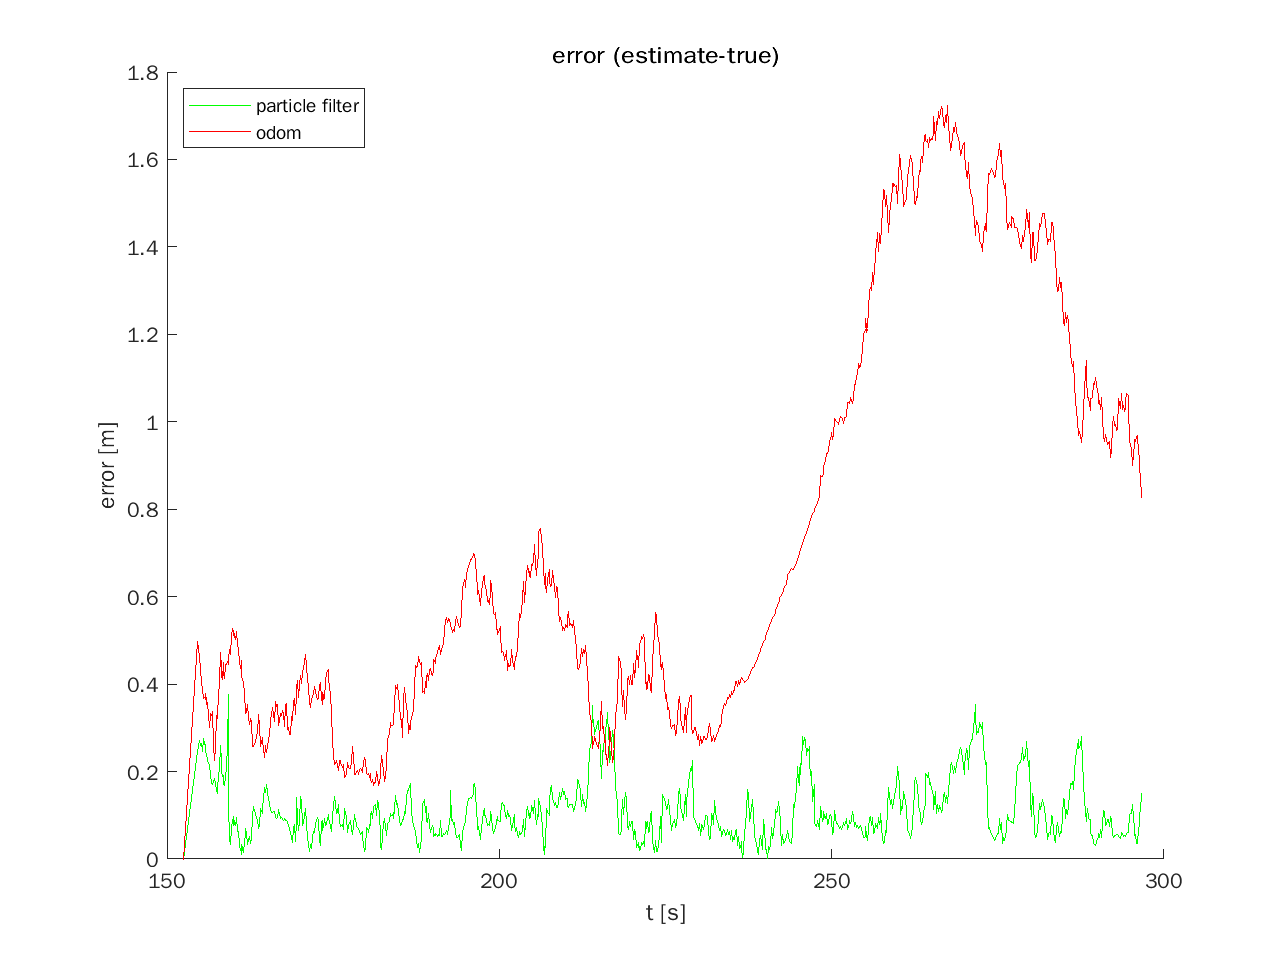

## Appendix - Source Code

### Helper Functions

function [x_idxs, y_idxs] = RayTrace(x_pixel, y_pixel, theta, angle, range)
% RAYTRACE - calculate pixel indexes of a ray given starting point, angle
% and range.
% INPUTS
% x_pixel (int), y_pixel (int) - start coordinates expressed in pixels
% theta (float)                - pose angle of robot/particle 
% angle (float)                - angle relative to pose angle of laser beam
% range (float)                - distance (meters) of laser beam
% OUTPUT
% x_idxs (1 x N array)         - x indices of pixels in path of ray
% y_idxs (1 x N array)         - y indices of pixels in path of ray

%laser scan range
r_max_laser = 10;

% make sure range does not exceed maximum laser range
if range > r_max_laser
    range = 10;
end

range_pixel = range/0.05;        % express range in terms of pixels
% disp('range_pixel:')
% disp(range_pixel)

% calculate angle of beam relative to x-axis
phi = theta + angle;             % angle wrt x-axis is theta + angle
phi = atan2(sin(phi), cos(phi)); % normalize angle between (-pi, pi)

% if beam angle (phi) is closer to y-axis (ex. between 45-135 degrees)
if (phi < 3*pi/4 && phi > pi/4) || (phi > -3*pi/4 && phi < -pi/4)
    % project range onto y-axis
    y_range_pixel = ceil(range_pixel*sin(phi));

    % reduce projection of range onto y-axis if projection exceeds bounds
    if y_range_pixel + y_pixel > 180
        y_range_pixel = 180-y_pixel;
    end
    if y_range_pixel + y_pixel < 0
        y_range_pixel = 0 - y_pixel;
    end

    % create an array of indices starting at 1/-1 to projected range
    if y_range_pixel < 0
        y_idxs = (1:abs(y_range_pixel))*-1;
    else
        y_idxs = 1:y_range_pixel;
    end
    x_idxs = y_idxs/tan(phi);   % calculate corresponding x index

% if beam angle (phi) is closer to x-axis (ex. between -45-45 degrees)
else
    % project range onto x-axis
    x_range_pixel = ceil(range_pixel*cos(phi));

    % reduce projection of range onto x-axis if projection exceeds bounds
    if x_range_pixel + y_pixel > 300
        x_range_pixel = 300-y_pixel;
    elseif x_range_pixel + x_pixel < 0
        x_range_pixel = 0 - x_pixel;
    end

    % create an array of indices starting at 1/-1 to projected range
    if x_range_pixel < 0
        x_idxs = (1:abs(x_range_pixel)) * -1;
    else
        x_idxs = 1:x_range_pixel;
    end
    y_idxs = x_idxs*tan(phi);  % calculate corresponding x index
end

% round indices to int
x_idxs = round(x_idxs + x_pixel,0);
y_idxs = round(y_idxs + y_pixel,0);
return


function [y_laser_pred] = PredictRange(x, y, theta, angle, ogp)
% PREDICTRANGE - Calculate laser range for a given pose, laser heading and
% occupancy grid.
% INPUTS
% x, y, theta (float)   - current pose of particle
% angle (float)         - laser heading wrt part.frame (theta = 0 degrees)
% ogp (180 x 300 array) - occupancy grid with probability of occupation
% OUTPUT
% y_laser_pred (float)  - predicted laser measurement

% INITIAL PARAMETERS

range_max = 10;                     % use max_distance + 2 x std_dev (0.5)
threshold = 0.5;                    % cell occupied if prob > 0.5

% convert from x,y coord to pixel coordinates
[x_pixel, y_pixel] = DistToPixel(x, y);
% find all pixels along ray from particle pose
[x_idxs, y_idxs] = RayTrace(x_pixel, y_pixel, theta, angle, range_max);

J = size(x_idxs, 2);                % number of pixels to test

% if J is empty, return range = 0
if J == 0
    y_laser_pred = 0;
    return
end

max_index = 1;  % index of furthest unoccupied pixel

% loop through each pixel from current particle until cell is occupied
for j=1:J
    % skip over indices if outside bounds
    if y_idxs(j) > 180 || x_idxs(j) > 300 || y_idxs(j) < 1 || x_idxs(j) < 1
        continue
    end
    if ogp(y_idxs(j),x_idxs(j)) >= threshold
        max_index = j;
        break
    end
end

% convert end point from pixel back to x,y coords
[x_end, y_end] = PixelToDist(x_idxs(max_index), y_idxs(max_index));

% calculate euclidean distance between particle loc to ray end point
y_laser_pred = sqrt((x_end - x)^2 + (y_end - y)^2);
return

%----------------------------------------------------------------------
function [x_pixel, y_pixel] = DistToPixel(x_coord, y_coord)
% DISTTOPIXEL - convert x, y coordinates from meters to pixels

ogxmin = -7;        % minimum x-value in meters
ogymin = -3;        % minimum y-value in meters
ogres = 0.05;       % resolution: 1 pixel = 0.05m 

x_pixel = floor((x_coord-ogxmin)/ogres);        % (x-(-7))/0.05
y_pixel = floor((y_coord-ogymin)/ogres);        % (y -(-3))/0.05
return

%----------------------------------------------------------------------
function [x_coord, y_coord] = PixelToDist(x_pixel, y_pixel)
% PIXELTODIST - convert x, y coordinates from pixels to meters

ogxmin = -7;        % minimum x-value in meters
ogymin = -3;        % minimum y-value in meters
ogres = 0.05;       % resolution: 1 pixel = 0.05m 

x_coord = (x_pixel*ogres) + ogxmin;             % (x_p*0.05)+(-7)
y_coord = (y_pixel*ogres) + ogymin;             % (y_p*0.05)+(-3)
return

%----------------------------------------------------------------------
function [prob] = ProbFromLogOdds(logodds)
%PROBFROMLOGODDS - Calculate probability between [0,1] given a log-odd

prob = exp(logodds)./(1.+exp(logodds));
return

### Question 1 - Occupancy Mapping Code

% =========
% ass3_q1.m
% =========
%
% This assignment will introduce you to the idea of first building an
% occupancy grid then using that grid to estimate a robot's motion using a
% particle filter.
% 
% There are two questions to complete (5 marks each):
%
%    Question 1: code occupancy mapping algorithm 
%    Question 2: see ass3_q2.m
%
% Fill in the required sections of this script with your code, run it to
% generate the requested plot/movie, then paste the plots into a short report
% that includes a few comments about what you've observed.  Append your
% version of this script to the report.  Hand in the report as a PDF file
% and the two resulting AVI files from Questions 1 and 2.
%
% requires: basic Matlab, 'gazebo.mat'
%
% T D Barfoot, January 2016
%
clear all;

% set random seed for repeatability
rng(1);

% ==========================
% load the dataset from file
% ==========================
%
%    ground truth poses: t_true x_true y_true theta_true
% odometry measurements: t_odom v_odom omega_odom
%           laser scans: t_laser y_laser
%    laser range limits: r_min_laser r_max_laser
%    laser angle limits: phi_min_laser phi_max_laser
%
load gazebo.mat;

% =======================================
% Question 1: build an occupancy grid map
% =======================================
%
% Write an occupancy grid mapping algorithm that builds the map from the
% perfect ground-truth localization.  Some of the setup is done for you
% below.  The resulting map should look like "ass2_q1_soln.png".  You can
% watch the movie "ass2_q1_soln.mp4" to see what the entire mapping process
% should look like.  At the end you will save your occupancy grid map to
% the file "occmap.mat" for use in Question 2 of this assignment.

% allocate a big 2D array for the occupancy grid
ogres = 0.05;                   % resolution of occ grid
ogxmin = -7;                    % minimum x value
ogxmax = 8;                     % maximum x value
ogymin = -3;                    % minimum y value
ogymax = 6;                     % maximum y value
ognx = (ogxmax-ogxmin)/ogres;   % number of cells in x direction
ogny = (ogymax-ogymin)/ogres;   % number of cells in y direction
oglo = zeros(ogny,ognx);        % occupancy grid in log-odds format
ogp = zeros(ogny,ognx);         % occupancy grid in probability format

% precalculate some quantities
numodom = size(t_odom,1);
npoints = size(y_laser,2);
angles = linspace(phi_min_laser, phi_max_laser,npoints);
dx = ogres*cos(angles);
dy = ogres*sin(angles);

% interpolate the noise-free ground-truth at the laser timestamps
t_interp = linspace(t_true(1),t_true(numodom),numodom);
x_interp = interp1(t_interp,x_true,t_laser);
y_interp = interp1(t_interp,y_true,t_laser);
theta_interp = interp1(t_interp,theta_true,t_laser);
omega_interp = interp1(t_interp,omega_odom,t_laser);

% set up the plotting/movie recording
vid = VideoWriter('ass3_q1.avi');
open(vid);
figure(1);
clf;
pcolor(ogp);
colormap(1-gray);
shading('flat');
axis equal;
axis on;
M = getframe;
writeVideo(vid,M);

% loop over laser scans (every fifth)
for t=1:5:989 %:size(t_laser,1)
    
    % convert current pose coords to pixels
    [x_pixel, y_pixel] = DistToPixel(x_interp(t), y_interp(t));

    % loop over every laser reading
    for i=1:npoints

        % if laser is below min range or NaN, skip over
        if y_laser(t,i) < r_min_laser || isnan(y_laser(t,i))
            continue
        end
        
        % calculate pixel indexes for laser
        [x_idxs, y_idxs] = RayTrace(x_pixel, y_pixel, theta_interp(t), ...
            angles(i), y_laser(t,i));

        % iterate over each cell index pair
        for j=1:size(x_idxs, 2)
           
            % skip over any instances where index is outside map
            if y_idxs(j) > 180 || x_idxs(j) > 300 || y_idxs(j) == 0 || ...
                    x_idxs(j) == 0
                continue
            end 
            % update log-odds
            if j < (size(x_idxs,2))
                % all cells except last cell are set as free
                oglo(y_idxs(j),x_idxs(j)) = oglo(y_idxs(j),x_idxs(j)) - 0.55;
            else
                % last cell is set as occupied
                oglo(y_idxs(j),x_idxs(j)) = oglo(y_idxs(j),x_idxs(j)) + 2;
            end
                
            % update probability array from log-odd data
            %ogp(y_idxs(j),x_idxs(j)) = ProbFromLogOdds( ...
            %    oglo(y_idxs(j),x_idxs(j)));
        end
    end

    % Update probability array from log-odd array
    ogp = ProbFromLogOdds(oglo);

    
    % ------end of your occupancy grid mapping algorithm-------

    % draw the map
    clf;
    pcolor(ogp);
    colormap(1-gray);
    shading('flat');
    axis equal;
    axis on;
    
    % draw the robot
    hold on;
    x = (x_interp(t)-ogxmin)/ogres;
    y = (y_interp(t)-ogymin)/ogres;
    th = theta_interp(t);
    r = 0.15/ogres;
    r2= y_laser(t,320);
    set(rectangle( 'Position', [x-r y-r 2*r 2*r], 'Curvature', [1 1]), ...
        'LineWidth',2,'FaceColor',[0.35 0.35 0.75]);
    set(plot([x x+r*cos(th)]', [y y+r2*sin(th)]', 'r-'),'LineWidth',2);
    
    % save the video frame
    M = getframe;
    writeVideo(vid,M);
    
    pause(0.1);
    
end

close(vid);
print -dpng ass3_q1.png

save occmap.mat ogres ogxmin ogxmax ogymin ogymax ognx ogny oglo ogp;

### Question 2 - Particle Filter Localization

% =========
% ass3_q2.m
% =========
%
% This assignment will introduce you to the idea of first building an
% occupancy grid then using that grid to estimate a robot's motion using a
% particle filter.
% 
% There are three questions to complete (5 marks each):
%
%    Question 1: see ass3_q1.m 
%    Question 2: code particle filter to localize from known map
%
% Fill in the required sections of this script with your code, run it to
% generate the requested plot/movie, then paste the plots into a short report
% that includes a few comments about what you've observed.  Append your
% version of this script to the report.  Hand in the report as a PDF file
% and the two resulting AVI files from Questions 1 and 2.
%
% requires: basic Matlab, 'gazebo.mat', 'occmap.mat'
%
% T D Barfoot, January 2016
%
clear all;

% set random seed for repeatability
rng(1);

% ==========================
% load the dataset from file
% ==========================
%
%    ground truth poses: t_true x_true y_true theta_true
% odometry measurements: t_odom v_odom omega_odom
%           laser scans: t_laser y_laser
%    laser range limits: r_min_laser r_max_laser
%    laser angle limits: phi_min_laser phi_max_laser
%
load gazebo.mat;

% ================================================
% load the occupancy map from question 1 from file
% ================================================
%  ogres: resolution of occ grid
% ogxmin: minimum x value
% ogxmax: maximum x value
% ogymin: minimum y value
% ogymax: maximum y value
%   ognx: number of cells in x direction
%   ogny: number of cells in y direction
%   oglo: occupancy grid in log-odds format
%    ogp: occupancy grid in probability format
load occmap.mat;

% =========================================================================
% Question 2: localization from an occupancy grid map using particle filter
% =========================================================================
%
% Write a particle filter localization algorithm to localize from the laser
% rangefinder readings, wheel odometry, and the occupancy grid map you
% built in Question 1.  We will only use two laser scan lines at the
% extreme left and right of the field of view, to demonstrate that the
% algorithm does not need a lot of information to localize fairly well.  To
% make the problem harder, the below lines add noise to the wheel odometry
% and to the laser scans.  You can watch the movie "ass2_q2_soln.mp4" to 
% see what the results should look like.  The plot "ass2_q2_soln.png" shows
% the errors in the estimates produced by wheel odometry alone and by the
% particle filter look like as compared to ground truth; we can see that
% the errors are much lower when we use the particle filter.

% interpolate the noise-free ground-truth at the laser timestamps
numodom = size(t_odom,1);
t_interp = linspace(t_true(1),t_true(numodom),numodom);
x_interp = interp1(t_interp,x_true,t_laser);
y_interp = interp1(t_interp,y_true,t_laser);
theta_interp = interp1(t_interp,theta_true,t_laser);
%omega_interp = interp1(t_interp,omega_odom,t_laser);

% interpolate the wheel odometry at the laser timestamps and
% add noise to measurements (yes, on purpose to see effect)
v_interp = interp1(t_interp,v_odom,t_laser) + 0.2*randn(size(t_laser,1),1);
omega_interp = interp1(t_interp,omega_odom,t_laser) + 0.04*randn(size(t_laser,1),1);

% add noise to the laser range measurements (yes, on purpose to see effect)
% and precompute some quantities useful to the laser
y_laser = y_laser + 0.1*randn(size(y_laser));
npoints = size(y_laser,2);                              % 640 laser scans
angles = linspace(phi_min_laser, phi_max_laser,npoints);% 640 angles
dx = ogres*cos(angles);
dy = ogres*sin(angles);
y_laser_max = 5;        % don't use laser measurements beyond this distance

% particle filter tuning parameters (yours may be different)
nparticles = 200;       % number of particles
v_noise = 0.2;          % noise on longitudinal speed for propagating particle
u_noise = 0.2;          % noise on lateral speed for propagating particle
omega_noise = 0.04;     % noise on rotational speed for propagating particle
laser_var = 0.5^2;      % variance on laser range distribution (R)
w_gain = 10*sqrt( 2 * pi * laser_var );     % gain on particle weight

% generate an initial cloud of particles
x_particle = x_true(1) + 0.5*randn(nparticles,1);
y_particle = y_true(1) + 0.3*randn(nparticles,1);
theta_particle = theta_true(1) + 0.1*randn(nparticles,1);

% compute a wheel odometry only estimate for comparison to particle
% filter
x_odom_only = x_true(1);
y_odom_only = y_true(1);
theta_odom_only = theta_true(1);

% error variables for final error plots - set the errors to zero at the start
pf_err(1) = 0;
wo_err(1) = 0;

% set up the plotting/movie recording
vid = VideoWriter('ass3_q2.avi');
open(vid);
figure(2);
clf;
hold on;
pcolor(ogp);
set(plot( (x_particle-ogxmin)/ogres, (y_particle-ogymin)/ogres, 'g.' ),'MarkerSize',10,'Color',[0 0.6 0]);
set(plot( (x_odom_only-ogxmin)/ogres, (y_odom_only-ogymin)/ogres, 'r.' ),'MarkerSize',20);
x = (x_interp(1)-ogxmin)/ogres;
y = (y_interp(1)-ogymin)/ogres;
th = theta_interp(1);
r = 0.15/ogres;
set(rectangle( 'Position', [x-r y-r 2*r 2*r], 'Curvature', [1 1]),'LineWidth',2,'FaceColor',[0.35 0.35 0.75]);
set(plot([x x+r*cos(th)]', [y y+r*sin(th)]', 'k-'),'LineWidth',2);
set(plot( (mean(x_particle)-ogxmin)/ogres, (mean(y_particle)-ogymin)/ogres, 'g.' ),'MarkerSize',20);
colormap(1-gray);
shading('flat');
axis equal;
axis on;
M = getframe;
writeVideo(vid,M);

% loop over 989 time-steps (each one has a laser scan)
for i=2:size(t_laser,1)
    % update the wheel-odometry-only algorithm
    dt = t_laser(i) - t_laser(i-1);                % time-step
    v = v_interp(i);                               % noisy input velocity
    omega = omega_interp(i);                       % noisy input ang. vel.
    x_odom_only = x_odom_only + dt*v*cos( theta_odom_only );
    y_odom_only = y_odom_only + dt*v*sin( theta_odom_only );
    phi = theta_odom_only + dt*omega;
    % normalize phi angle between -pi < phi < pi
    while phi > pi
        phi = phi - 2*pi;
    end
    while phi < -pi
        phi = phi + 2*pi;
    end 
    theta_odom_only = phi;
    w_particle = ones(nparticles, 1);
    % loop over the particles (N = 200 particles)
    for n=1:nparticles
        % propagate the particle forward in time using wheel odometry
        % (remember to add some unique noise to each particle so they
        % spread out over time)
        v = v_interp(i) + v_noise*randn(1);
        u = u_noise*randn(1);
        omega = omega_interp(i) + omega_noise*randn(1);
        x_particle(n) = x_particle(n) + dt*(v*cos( theta_particle(n) ) ...
            - u*sin( theta_particle(n) ));
        y_particle(n) = y_particle(n) + dt*(v*sin( theta_particle(n) ) ...
            + u*cos( theta_particle(n) ));
        phi = theta_particle(n) + dt*omega;

        while phi > pi
            phi = phi - 2*pi;
        end
        while phi < -pi
            phi = phi + 2*pi;
        end 
        theta_particle(n) = phi;

        % pose of particle in inertial frame
        T = [cos(theta_particle(n)) -sin(theta_particle(n)) x_particle(n); ...
             sin(theta_particle(n))  cos(theta_particle(n)) y_particle(n); ...
                     0                     0                 1];    

        % compute the weight for each particle using only 2 laser rays 
        % (right=beam 1 and left=beam 640)
        %w_particle(n) = 1.0;     
        for beam = 1:2
            if beam == 1
                j = 1;      % far-right beam
            else
                j = 640;    % far-left beam
            end

            % ------insert your particle filter weight calculation here ------

            %get predicted range: y_laser_pred
            [y_laser_pred] = PredictRange(x_particle(n), y_particle(n), ...
                theta_particle(n), angles(j), ogp);
            
            %discard laser readings that are above the max or that are NaN
            if y_laser(i, j) > y_laser_max || isnan(y_laser(i,j))
                continue
            end

            % calculate weight using gaussian pdf function
            w_particle(n) = w_particle(n)*w_gain*normpdf(y_laser(i, j), ...
                y_laser_pred, sqrt(laser_var));

        % ------end of your particle filter weight calculation-------
        end
        
    end    
        
    % resample the particles using Madow systematic resampling
    w_bounds = cumsum(w_particle)/sum(w_particle);
    w_target = rand(1);
    j = 1;
    for n=1:nparticles
       while w_bounds(j) < w_target
           j = mod(j,nparticles) + 1;
       end
       x_particle_new(n) = x_particle(j);
       y_particle_new(n) = y_particle(j);
       theta_particle_new(n) = theta_particle(j);
       w_target = w_target + 1/nparticles;
       if w_target > 1
           w_target = w_target - 1.0;
           j = 1;
       end
    end
    x_particle = x_particle_new;
    y_particle = y_particle_new;
    theta_particle = theta_particle_new;
     
    % save the translational error for later plotting
    pf_err(i) = sqrt( (mean(x_particle) - x_interp(i))^2 + (mean(y_particle) - y_interp(i))^2 );
    wo_err(i) = sqrt( (x_odom_only - x_interp(i))^2 + (y_odom_only - y_interp(i))^2 );
    
    % plotting
    figure(2);
    clf;
    hold on;
    pcolor(ogp);
    set(plot( (x_particle-ogxmin)/ogres, (y_particle-ogymin)/ogres, 'g.' ),'MarkerSize',10,'Color',[0 0.6 0]);
    set(plot( (x_odom_only-ogxmin)/ogres, (y_odom_only-ogymin)/ogres, 'r.' ),'MarkerSize',20);
    x = (x_interp(i)-ogxmin)/ogres;
    y = (y_interp(i)-ogymin)/ogres;
    th = theta_interp(i);
    if ~isnan(y_laser(i,1)) && y_laser(i,1) <= y_laser_max
       set(plot([x x+y_laser(i,1)/ogres*cos(th+angles(1))]', [y y+y_laser(i,1)/ogres*sin(th+angles(1))]', 'm-'),'LineWidth',1);
    end
    if ~isnan(y_laser(i,640)) && y_laser(i,640) <= y_laser_max
       set(plot([x x+y_laser(i,640)/ogres*cos(th+angles(640))]', [y y+y_laser(i,640)/ogres*sin(th+angles(640))]', 'm-'),'LineWidth',1);
    end
    r = 0.15/ogres;
    set(rectangle( 'Position', [x-r y-r 2*r 2*r], 'Curvature', [1 1]),'LineWidth',2,'FaceColor',[0.35 0.35 0.75]);
    set(plot([x x+r*cos(th)]', [y y+r*sin(th)]', 'k-'),'LineWidth',2);
    set(plot( (mean(x_particle)-ogxmin)/ogres, (mean(y_particle)-ogymin)/ogres, 'g.' ),'MarkerSize',20);
    colormap(1-gray);
    shading('flat');
    axis equal;
    axis on;
    
    % save the video frame
    M = getframe;
    writeVideo(vid,M);

    pause(0.01);
   
end

close(vid);

% final error plots
figure(3);
clf;
hold on;
plot( t_laser, pf_err, 'g-' );
plot( t_laser, wo_err, 'r-' );
xlabel('t [s]');
ylabel('error [m]');
legend('particle filter', 'odom', 'Location', 'NorthWest');
title('error (estimate-true)');
print -dpng ass3_q2.png